# Panel models (no cross-sections)

% cleaning

clear
close all
rehash path

addpath ../sandbox
addpath ../bear



## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];


## Prepare data and a reduced-form model


inputTbx = tablex.fromCsv("panel_data.csv");

estimStart = datex.q(1972,1);
estimEnd = datex.q(2014,4);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["YER", "HICSA", "STN"], ...
    units=["US", "EA", "UK"], ...
    exogenous=["Oil"], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=12, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);

dataH = model.DataHolder(meta, inputTbx);



## Mean OLS and Normal Wishart Models


numSamples = 10;

estimatorR1 = estimator.MeanOLSPanel(meta);
estimatorR1.Settings

ans =   MeanOLSPanel with properties:

            Burnin: 0
         Exogenous: [9×2 logical]
    BlockExogenous: 0
    Autoregression: [9×1 double]
           Lambda1: 0.1000
           Lambda2: 0.5000
           Lambda3: 1
           Lambda4: [9×2 double]
           Lambda5: 1.0000e-03




estimatorR2 = estimator.NormalWishartPanel(meta);

modelR1 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
    , stabilityThreshold=Inf ...
);

modelR2 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR2 ...
    , stabilityThreshold=Inf ...
);

rng(0)
modelR1.initialize();
info1 = modelR1.presample(numSamples);

 Presampling model.ReducedForm (MeanOLSPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



% disp('Beta Median OLS Model:')
% betaMedian1 = calcMedian(modelR1,"beta");

rng(0)
modelR2.initialize();
info2 = modelR2.presample(numSamples);

 Presampling model.ReducedForm (NormalWishartPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



% disp('Beta Median Normal Wishart Model:')
% betaMedian2 = calcMedian(modelR2,"beta");




## Random Effect Models


estimatorR3 = estimator.ZellnerHongPanel(meta);
estimatorR3.Settings

ans =   ZellnerHongPanel with properties:

            Burnin: 0
         Exogenous: [9×2 logical]
    BlockExogenous: 0
    Autoregression: [9×1 double]
           Lambda1: 0.1000
           Lambda2: 0.5000
           Lambda3: 1
           Lambda4: [9×2 double]
           Lambda5: 1.0000e-03



estimatorR4 = estimator.HierarchicalPanel(meta);
estimatorR4.Settings

ans =   HierarchicalPanel with properties:

                S0: 1.0000e-03
                V0: 1.0000e-03
            Burnin: 0
         Exogenous: [9×2 logical]
    BlockExogenous: 0
    Autoregression: [9×1 double]
           Lambda1: 0.1000
           Lambda2: 0.5000
           Lambda3: 1
           Lambda4: [9×2 double]
           Lambda5: 1.0000e-03



modelR3 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR3 ...
    , stabilityThreshold=Inf ...
);

modelR4 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR4 ...
    , stabilityThreshold=Inf ...
);

rng(0)
modelR3.initialize();
info3 = modelR3.presample(numSamples);

 Presampling model.ReducedForm (ZellnerHongPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



% disp('Beta Median Zellner Hong Model:')
% betaMedian3 = calcMedian(modelR3,"beta")

rng(0)
modelR4.initialize();
info4 = modelR4.presample(numSamples);

 Presampling model.ReducedForm (HierarchicalPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



% disp('Beta Median Hierarchical Model:')
% betaMedian4 = calcMedian(modelR4,"beta")



## Estimate residuals


resid1 = modelR1.estimateResiduals();
resid2 = modelR2.estimateResiduals();
resid3 = modelR3.estimateResiduals();
resid4 = modelR4.estimateResiduals();



## Run unconditional forecast


fcastStart = datex.shift(estimEnd, -9);
fcastEnd = datex.shift(estimEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);

fcast1 = modelR1.forecast(fcastSpan);
fcast2 = modelR2.forecast(fcastSpan);
fcast3 = modelR3.forecast(fcastSpan);
fcast4 = modelR4.forecast(fcastSpan);



## Indentify a SVAR using Cholesky (without reordering)


identChol = identifier.Cholesky(order=["HICSA", "STN"]);

modelS1 = model.Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();
info1 = modelS1.presample(numSamples);

 Presampling model.Structural (MeanOLSPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




modelS2 = model.Structural(reducedForm=modelR2, identifier=identChol);
modelS2.initialize();
info2 = modelS2.presample(numSamples);

 Presampling model.Structural (NormalWishartPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




modelS3 = model.Structural(reducedForm=modelR3, identifier=identChol);
modelS3.initialize();
info3 = modelS3.presample(numSamples);

 Presampling model.Structural (ZellnerHongPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




modelS4 = model.Structural(reducedForm=modelR4, identifier=identChol);
modelS4.initialize();
info4 = modelS4.presample(numSamples);

 Presampling model.Structural (HierarchicalPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



## Simulate shock responses


resp1 = modelS1.simulateResponses();
resp2 = modelS2.simulateResponses();
resp3 = modelS3.simulateResponses();
resp4 = modelS4.simulateResponses();


## Plot results

respTbx1 = tablex.apply(resp1, prctileFunc);
respTbx1 = tablex.flatten(respTbx1);

respTbx1

respTbx1 = 16×27 timetable
     Time                    US_YER___DEM                              US_YER___SUP                           US_YER___POL                       US_HICSA___DEM                        US_HICSA___SUP                          US_HICSA___POL                       US_STN___DEM                     US_STN___SUP                     US_STN___POL                           EA_YER___DEM                              EA_YER___SUP                           EA_YER___POL                       EA_HICSA___DEM                        EA_HICSA___SUP                          EA_HICSA___POL                       EA_STN___DEM                     EA_STN___SUP                     

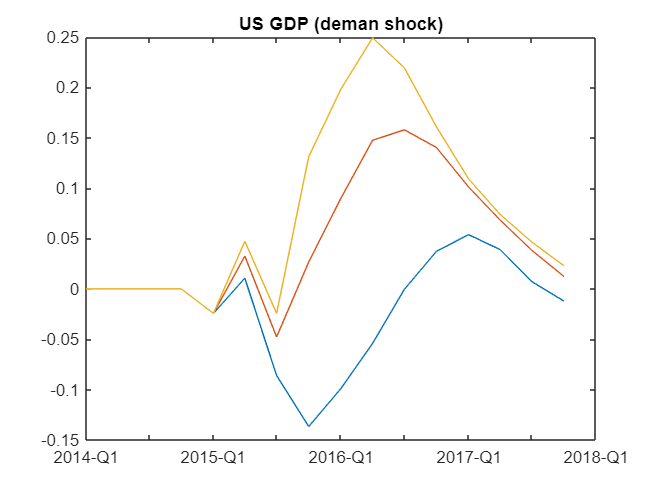


tablex.plot(respTbx1,"US_YER___DEM");
title("US GDP (deman shock)");

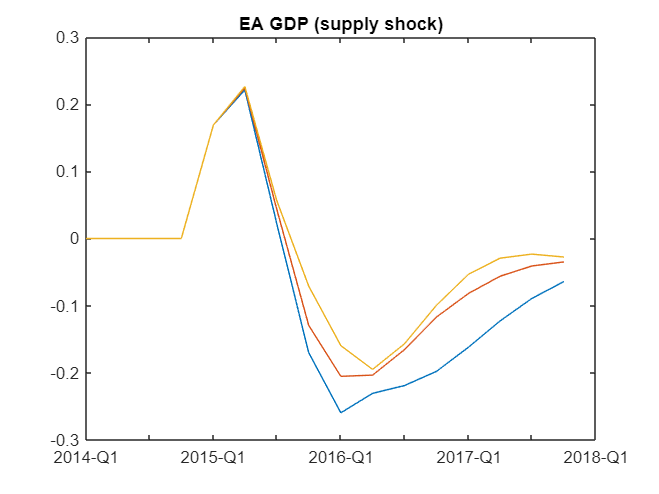


tablex.plot(respTbx1,"EA_YER___SUP");
title("EA GDP (supply shock)");

## Uncoditional forecast

fcastStart = datex.shift(modelS1.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelS1.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);


Mean OLS

fcastTbx1 = modelS1.forecast(fcastSpan);
fcastPrctileTbx1 = tablex.apply(fcastTbx1, prctileFunc);
fcastPrctileTbx1 = tablex.flatten(fcastPrctileTbx1);

fcastTbx1

fcastTbx1 = 15×18 timetable
     Time        US_YER        US_HICSA        US_STN         EA_YER        EA_HICSA        EA_STN         UK_YER        UK_HICSA        UK_STN       resid_US_YER    resid_US_HICSA    resid_US_STN    resid_EA_YER    resid_EA_HICSA    resid_EA_STN    resid_UK_YER    resid_UK_HICSA    resid_UK_STN
    _______    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ____________   

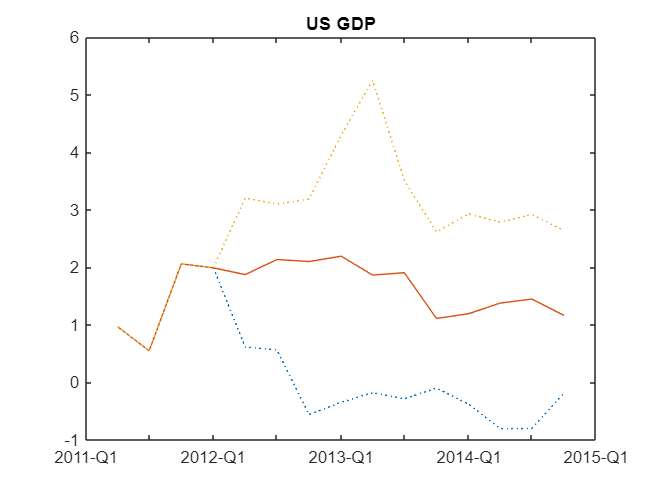

dataTbx = 12×10 timetable
     Time      US_YER    US_HICSA    US_STN    EA_YER    EA_HICSA    EA_STN    UK_YER    UK_HICSA    UK_STN     Oil 
    _______    ______    ________    ______    ______    ________    ______    ______    ________    ______    _____

    2015-Q1      NaN       NaN        NaN       NaN        NaN        NaN       NaN        NaN        NaN      94.32
    2015-Q2      NaN       NaN        NaN       NaN        NaN        NaN       NaN        NaN        NaN      94.32
    2015-Q3      NaN       NaN        NaN       NaN        NaN        NaN       

planTbx = 12×9 timetable
     Time      US_YER    US_HICSA    US_STN    EA_YER    EA_HICSA    EA_STN    UK_YER    UK_HICSA    UK_STN
    _______    ______    ________    ______    ______    ________    ______    ______    ________    ______

    2015-Q1      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q2      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q3      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q4      ""       

 Conditional forecast [10]
 ◼―――――――――――――――――――――――――――――――――――――――――――――――――  0% 

Error using  .' 
TRANSPOSE does not support N-D arrays. Use PAGETRANSPOSE/PAGECTRANSPOSE to transpose pages or PERMUTE to reorder dimensions of N-D arrays.

Error in conditional.forecast (line 18)
    Y = transpose(flipud(initY));

Error in model/Structural/conditionalForecast (


tablex.plot( ...
    fcastPrctileTbx1, "US_YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);
title("US GDP");

## Calcuate FEVD


fevd1 = modelS1.calculateFEVD();
fevd2 = modelS2.calculateFEVD();
fevd3 = modelS3.calculateFEVD();
fevd4 = modelS4.calculateFEVD();